nh_nsc = dicomread("C0000001.dcm");
yh_nsc = dicomread("C0000002.dcm");
nh_ysc = dicomread("C0000003.dcm");
gain_vol = dicomread("C0000004.dcm");
swe_vol = dicomread("C0000006.dcm");
swe_im = dicomread("I0000005.dcm");


sz_nn = size(nh_nsc);
sz_yn = size(yh_nsc);
sz_ny = size(nh_ysc);
sz_gain = size(gain_vol);
sz_swe = size(swe_vol);
sz_im = size(swe_im);


[crp1, nh_nsc_crd] = imcrop(nh_nsc(:,:,:,1),[142.5 87.5 412 378])

crp1 = 379×413×3 uint8 array
crp1(:,:,1) =

    44    51    62    77    91   100   102    94    87    80    73    74    70    59    56    67    80    83    73    60    60    76    88    90    82    73    67    60    56    56    51    44    38    39    47    56    62    67    67    62    57    52    49    51    49    44    41    39    36    32    27    23    19    18    16    19    23    27    29    32    32    26    19    10     7    10    10    11    15    23    33    41    51    59    70    84    87    76    54    30    23    24    23    23    27    29    33    39    38    35    33    38    38    33    23    15    10    13    22    26    26    29    30    27    26    26    23    20    20    24    24    23    26    30    35    35    30    27    33    36    36    41    44    41    41    41    36    24    19    24    30    32    29    27    29    33    41    43    39    33    38    43    44    44    44    38    29    18    15    11    11    18    36    57    79    94    99    96    88  

nh_nsc_crd =   142.5000   87.5000  412.0000  378.0000


[crp2, yh_nsc_crd] = imcrop(yh_nsc(:,:,:,1),[142.5 87.5 412 378])

crp2 = 379×413×3 uint8 array
crp2(:,:,1) =

   125   111   102    97    86    77    84    99   109   116   119   113   107   107   104   101   110   124   128   121   121   126   127   123   113   108   103   104   104   101   111   120   131   136   138   134   122   110   104   104   102    95    86    76    71    91   110   116   115   116   118   115   104    86    73    64    59    59    62    82    87    86    90    92    91    90    90    87    70    67    77    70    65    60    54    51    43    39    57    65    56    39    36    54    65    94   114   101    79    92   103   110   111    96   109   124   133   137   129   108    95   109   123   121   112   107   106   101    96    91    82    68    59    52    47    49    47    49    74    95   104   114   118   108    82    67    57    57    67    64    68    77    77    84   102   111   113   109   102   104   103    99   103   107   107   109   109   101    92    88    92   101   103   104   111   118   116    94    56  

yh_nsc_crd =   142.5000   87.5000  412.0000  378.0000


[crp3, nh_ysc_crd] = imcrop(nh_ysc(:,:,:,1),[142.5 87.5 412 378])

crp3 = 379×413×3 uint8 array
crp3(:,:,1) =

    15    24    38    49    56    59    57    49    41    43    46    41    33    27    26    27    24    23    35    47    49    44    36    35    32    27    26    29    36    39    38    38    39    36    41    47    47    43    43    47    44    36    32    43    52    59    57    59    59    54    46    41    39    33    26    24    33    41    60    79    82    88    95    95    88    76    64    52    51    59    60    60    64    62    62    60    57    56    59    70    73    67    59    65    73    79    86    87    77    67    73    74    84   100   107    96    87    84    84    84    84    83    80    77    86    92    96    95    87    79    65    62    83    87    86    83    76    79    82    86    90    86    82    84    80    68    71    71    73    73    74    76    80    83    82    73    71    73    71    77    77    67    64    68    76    80    76    67    62    64    79    84    76    65    70    82    86    77    68  

nh_ysc_crd =   142.5000   87.5000  412.0000  378.0000


[crp4, gain_crd] = imcrop(gain_vol(:,:,:,1),[142.5 87.5 412 378])

crp4 = 379×413×3 uint8 array
crp4(:,:,1) =

   152   137   128   120   119   133   140   137   142   153   164   169   163   160   156   156   158   156   153   152   141   146   154   166   170   166   164   157   150   156   166   161   156   144   128   141   147   145   148   156   162   167   169   171   171   175   175   166   163   153   146   144   140   140   147   158   162   169   171   168   156   158   165   164   161   164   166   162   164   171   167   162   162   163   164   165   166   161   160   171   177   175   178   175   168   164   161   163   168   172   171   165   164   161   153   151   160   171   175   176   178   171   163   168   178   180   184   182   178   171   161   162   171   175   175   171   170   179   183   175   168   171   165   147   142   165   172   167   172   177   178   175   169   168   175   176   171   167   158   156   164   167   166   164   164   167   161   153   159   171   176   177   179   175   172   171   175   179   177  

gain_crd =   142.5000   87.5000  412.0000  378.0000


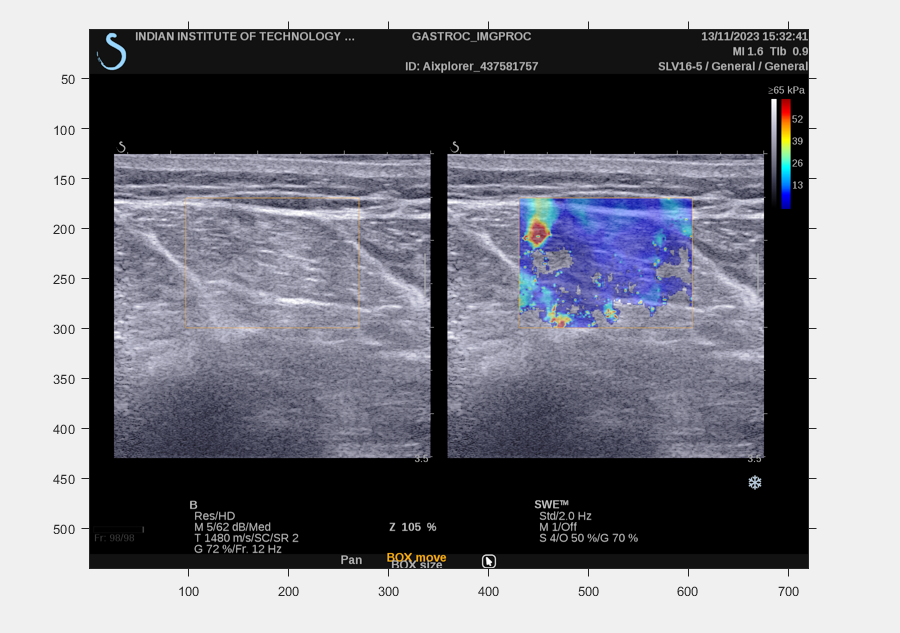

crp5 = 298×310×3 uint8 array
crp5(:,:,1) =

   136   126   133   142   147   148   141   136   135   145   150   154   153   149   135   138   144   132   118   124   131   136   145   146   145   145   142   152   152   143   131   114   107   116   133   141   142   142   146   146   149   152   147   136   147   149   139   122   115   119   124   126   128   126   135   144   151   142   137   147   153   152   145   139   146   159   166   172   168   163   176   180   168   154   160   164   167   172   167   155   152   164   168   160   166   168   171   171   180   189   186   177   178   175   159   152   164   167   171   182   175   181   196   188   161   159   177   181   180   178   175   175   173   171   168   166   169   175   183   200   208   197   188   182   166   152   160   165   175   186   185   172   178   175   178   175   172   166   149   161   165   159   165   178   182   175   178   185   177   164   181   201   212   210   194   180   176   175   170  

swe_crd =   361.5100  129.5100  309.9800  297.9800


[crp5, swe_crd] = imcrop(swe_vol(:,:,:,1))



xref1 = floor([nh_nsc_crd(1),nh_nsc_crd(1)+nh_nsc_crd(3)])

xref1 =    142   554


yref1 = floor([nh_nsc_crd(2),nh_nsc_crd(2)+nh_nsc_crd(4)])

yref1 =     87   465


xref2 = floor([yh_nsc_crd(1),yh_nsc_crd(1)+yh_nsc_crd(3)])

xref2 =    142   554


yref2 = floor([yh_nsc_crd(2),yh_nsc_crd(2)+yh_nsc_crd(4)])

yref2 =     87   465


xref3 = floor([nh_ysc_crd(1),nh_ysc_crd(1)+nh_ysc_crd(3)])

xref3 =    142   554


yref3 = floor([nh_ysc_crd(2),nh_ysc_crd(2)+nh_ysc_crd(4)])

yref3 =     87   465


xref4 = floor([gain_crd(1),gain_crd(1)+gain_crd(3)])

xref4 =    142   554


yref4 = floor([gain_crd(2),gain_crd(2)+gain_crd(4)])

yref4 =     87   465


xref5 = floor([swe_crd(1),swe_crd(1)+swe_crd(3)])

xref5 =    361   671


yref5 = floor([swe_crd(2),swe_crd(2)+swe_crd(4)])

yref5 =    129   427



vol_nn = squeeze(nh_nsc(yref1(1):yref1(2),xref1(1):xref1(2),1,:))

vol_nn = 379×413×148 uint8 array
vol_nn(:,:,1) =

    62    67    79    94   103   108   108   104    95    80    64    57    59    57    49    52    59    59    52    46    44    54    60    65    67    62    57    56    52    46    39    36    38    39    39    39    33    30    27    29    30    32    36    36    36    33    32    35    44    47    46    41    33    30    33    36    38    41    38    38    39    39    35    32    33    33    35    33    33    38    39    43    46    52    57    62    65    67    62    51    41    46    49    43    46    52    51    51    56    60    57    52    51    52    54    52    47    43    46    52    54    51    51    56    56    56    54    49    44    39    39    41    39    39    39    41    41    41    38    36    35    38    43    44    47    49    49    43    36    35    43    51    52    54    54    57    60    59    59    59    59    73    79    77    70    56    41    33    30    27    30    33    51    84   107   122   133   135  

vol_yn = squeeze(yh_nsc(yref2(1):yref2(2),xref2(1):xref2(2),1,:))

vol_yn = 379×413×139 uint8 array
vol_yn(:,:,1) =

   131   115    90    82    96   108   114   122   127   126   129   133   132   124   119   113   114   122   125   125   128   124   121   123   122   117   113   112   114   115   113   111   115   124   132   134   129   119   109   109   108   101   102   110   103    86   101   116   115   106   116   130   131   122   107    92    82    82    82    87    91    84    74    77    83    76    71    86    96    95    92    92    88    84    82    80    80    71    65    86    97    97    92    99   107   103   113   129   129   115    97   106   119   123   121   126   133   136   135   128   112    95    96   113   121   122   122   126   127   123   112    99    92   101   101    83    79    87    83   104   122   125   121   122   119   110   114   115   102    99   106   114   114   108   102   100   107   113   118   123   126   121   108   100   100   103   111   114   112   103    91    83    86    94   102   117   128   126  

vol_ny = squeeze(nh_ysc(yref3(1):yref3(2),xref3(1):xref3(2),1,:))

vol_ny = 379×413×148 uint8 array
vol_ny(:,:,1) =

    35    33    36    44    60    73    70    60    49    44    46    52    54    49    44    43    39    32    30    39    51    65    73    70    59    52    54    56    54    57    67    67    57    52    60    73    82    80    71    64    62    59    52    47    54    57    60    62    64    60    52    46    47    52    56    52    46    43    46    52    57    59    68    77    79    77    67    54    51    70    87    90    86    87    86    76    74    84    80    71    83    91    80    60    67    76    73    70    68    65    71    84    90    86    79    77    73    62    64    73    76    79    77    67    60    77    87    90    87    80    73    62    54    54    52    60    68    73    76    73    65    64    60    57    57    57    56    56    59    64    59    54    56    59    57    60    71    77    77    77    79    82    83    83    86    84    84    87    91    92    91    95    99    99    97    96    97    95  

vol_gain = squeeze(gain_vol(yref4(1):yref4(2),xref4(1):xref4(2),1,:))

vol_gain = 379×413×148 uint8 array
vol_gain(:,:,1) =

   141   135   123   123   132   138   145   149   152   150   147   149   145   134   146   161   167   166   160   153   153   156   158   155   149   145   141   141   142   139   146   163   168   171   168   160   152   136   131   135   142   152   164   172   175   176   178   178   167   150   140   135   133   135   142   144   135   134   142   142   145   152   154   155   152   150   155   151   152   157   159   160   162   164   162   160   158   159   157   152   159   166   171   171   164   162   164   167   165   164   162   159   157   162   166   164   164   167   165   161   166   168   160   152   150   164   174   167   161   165   164   148   142   157   163   165   168   165   161   167   163   152   156   163   156   149   160   168   164   161   165   168   167   168   168   167   162   153   149   156   160   152   149   152   152   150   146   143   147   146   151   158   167   169   168   167   164   1

vol_swe = swe_vol(yref5(1):yref5(2),xref5(1):xref5(2),:,:)

vol_swe = 299×311×3×98 uint8 array
vol_swe(:,:,1,1) =

   132   126   135   147   147   145   142   133   128   128   124   123   136   141   129   125   132   134   142   144   141   123   125   142   151   150   138   126   142   147   141   116   116   133   142   145   143   157   164   163   153   138   149   157   137   142   142   152   145   138   147   163   160   168   176   171   173   186   192   187   178   178   180   177   173   164   154   152   163   168   164   166   164   162   166   165   167   168   168   163   156   160   168   162   151   160   164   160   164   172   170   163   159   162   160   156   158   171   181   178   173   170   177   179   171   160   156   160   165   167   165   162   172   186   187   179   174   173   174   175   180   175   164   156   156   147   134   138   147   159   169   174   178   178   168   161   162   167   164   166   169   164   159   168   171   159   154   155   153   147   142   154   162   168   168   160   156   

volshow(vol_nn)

ans =   volshow with properties:

                 Parent: [1×1 Panel]
               Alphamap: [256×1 double]
               Colormap: [256×3 double]
               Lighting: 1
        IsosurfaceColor: [1 0 0]
               Isovalue: 0.5000
               Renderer: 'VolumeRendering'
         CameraPosition: [4 4 2.5000]
         CameraUpVector: [0 0 1]
           CameraTarget: [0 0 0]
        CameraViewAngle: 15
        BackgroundColor: [0.2150 0.2150 0.2750]
           ScaleFactors: [1 1 1]
    InteractionsEnabled: 1
